% This code assesses the results of processing a dataset consisting of
% images with two rings with initial beta2 values of -1 (outer) and 2 (inner),
% which are changed by either +/- 0.2 until they switch to 2 (outer) and -1 (inner). 

% see "process_through_network_differentb2.mlx" for how these images were
% produced

% MPhys Research Project 2022/23
% Ross Anderson (H00295702)



% clear commands
clc
clear
close all

% set the run number, this is indicated by the gdrive file
run_no = 24;

% load all aspects of that run
load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\results_process.mat");
% load("G:\My Drive\MPhys Project\run_"+run_no+"\history.mat");
images_sampled_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\centroid_process.mat");
images_gaussfilt_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\gaussfilt_process.mat");
% images_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\images.mat");
coeffs = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\coeffs_process.mat");
% coeffs = coeffs.coeffs;

% extracting images
images_sampled_mat = images_sampled_mat.images_sampled_mat;
images_gaussfilt_mat = images_gaussfilt_mat.images_gaussfilt_mat;

% convert the network_output to the correct dimensionality
network_output = results.predictions;
network_output = permute(network_output, [2, 3, 1]);


% number of images in dataset
N = 16;

for i = 1:N

    gaussfilt_tot = flipcat_4fold(images_gaussfilt_mat(:,:,i));
    %     showim(gaussfilt_tot, 1)
    %     title("Network input")
    %     shading flat

    sampled_tot = flipcat_4fold(images_sampled_mat(:,:,i));
    %     showim(sampled_tot, 1)
    %     title("Truth")
    %     shading flat

    network_output_tot = flipcat_4fold(network_output(:, :, i));
    %     showim(network_output_tot, 1)
    %     title("Network output")
    %     shading flat


    %     showim(InvAbel(gaussfilt_tot), 1)
    %     title("Network input")
    %     shading flat

    %     showim(InvAbel(sampled_tot), 1)
    %     title("Truth")
    %     shading flat

    %     showim(InvAbel(network_output_tot), 1)
    %     title("Network output")
    %     shading flat


    [v_input, r] = velocity_dist(gaussfilt_tot, 96);
    %     plot(r, v_input, "LineWidth", 2)
    %     xlim([0, max(r)])
    %     ylim([-0.1, 1.1])
    %     xlabel("Radius (pixels)", "FontSize", 18)
    %     ylabel("Integrated signal (arb.)", "FontSize", 18)
    %     title("Input")

    [v_truth, r] = velocity_dist(sampled_tot, 96);
    %     plot(r, v_truth, "LineWidth", 2)
    %     xlim([0, max(r)])
    %     ylim([-0.1, 1.1])
    %     xlabel("Radius (pixels)", "FontSize", 18)
    %     ylabel("Integrated signal (arb.)", "FontSize", 18)
    %     title("Truth")

    [v_output, r] = velocity_dist(network_output_tot, 96);
    %     plot(r, v_output, "LineWidth", 2)
    %     xlim([0, max(r)])
    %     ylim([-0.1, 1.1])
    %     xlabel("Radius (pixels)", "FontSize", 18)
    %     ylabel("Integrated signal (arb.)", "FontSize", 18)
    %     title("Output")


    %     plot(r, v_input)
    %     hold on
    %     plot(r, v_output)
    %     hold off
    %     xlim([0, max(r)])
    %     ylim([-0.1, 1.1])
    %     xlabel("Radius (pixels)")
    %     ylabel("Integrated signal (arb.)")
    %     title("Input vs Output - N = " + N)
    %     legend("Input", "Output")


    %     plot(r, v_truth)
    %     hold on
    %     plot(r, v_output)
    %     hold off
    %     xlim([0, max(r)])
    %     ylim([-0.1, 1.1])
    %     xlabel("Radius (pixels)")
    %     ylabel("Integrated signal (arb.)")
    %     title("Truth vs Output")sho
    %     legend("Truth", "Output")


    % extract beta2
    input_inverted = InvAbel(gaussfilt_tot);

    I_pol_original = cart_2_polar(input_inverted', [48,360]);
    I_pol_original(I_pol_original<0) = 0;
    % showim(I_pol_original, 1)
    % title("Find range")
    % shading flat

    range_min = 21;
    range_max = 31;

    beta2_input = find_beta2_customres(input_inverted, 96, range_min, range_max);

    truth_inverted = InvAbel(sampled_tot);
    beta2_truth = find_beta2_customres(truth_inverted, 96, range_min, range_max);

    output_inverted = InvAbel(network_output_tot);
    beta2_output = find_beta2_customres(output_inverted, 96, range_min, range_max);

    [~, locs_truth] = findpeaks(v_truth, 'NPeaks', 2, 'SortStr', 'descend');
    [~, locs_output] = findpeaks(v_output, 'NPeaks', 2, 'SortStr', 'descend');

    locs_output_r = r(locs_output);
    locs_truth_r = r(locs_truth);

    beta2_output_peaks = beta2_output(locs_output_r - range_min + 1);
    beta2_truth_peaks = beta2_truth(locs_truth_r - range_min + 1);

    output_ring1_error(i) = std(beta2_output(locs_output_r(1) - range_min:locs_output_r(1) - range_min + 2));
    output_ring2_error(i) = std(beta2_output(locs_output_r(2) - range_min:locs_output_r(2) - range_min + 2));
   
    truth_ring1_error(i) = std(beta2_truth(locs_truth_r(1) - range_min:locs_truth_r(1) - range_min + 2));
    truth_ring2_error(i) = std(beta2_truth(locs_truth_r(2) - range_min:locs_truth_r(2) - range_min + 2));

    output_ring1_beta2(i) = beta2_output_peaks(1);
    output_ring2_beta2(i) = beta2_output_peaks(2);

    truth_ring1_beta2(i) = beta2_truth_peaks(1);
    truth_ring2_beta2(i) = beta2_truth_peaks(2);

    beta2_output_peaks_all{i} = beta2_output_peaks;
    beta2_truth_peaks_all{i} = beta2_truth_peaks;

end


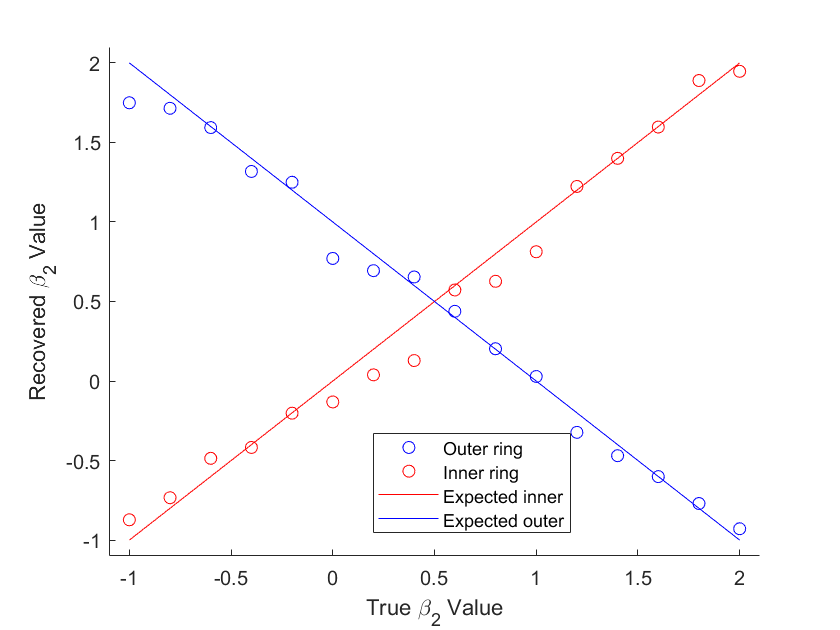

close all
figure()
hold on
plot(-1:0.2:2, nonzeros(output_ring1_beta2)', 'o', 'Color', 'blue')
plot(-1:0.2:2, nonzeros(output_ring2_beta2)', 'o', 'Color', 'red')
plot(-1:0.2:2, -1:0.2:2, 'Color', 'red')
plot(-1:0.2:2, 2:-0.2:-1, 'Color', 'blue')
xlabel("True \beta_2 Value")
ylabel("Recovered \beta_2 Value")
legend("Outer ring", "Inner ring", "Expected inner", "Expected outer", 'Position',[0.443452380952383 0.15357142857143 0.236309523809524 0.159126984126984]);
xlim([-1.1, 2.1])
ylim([-1.1, 2.1])

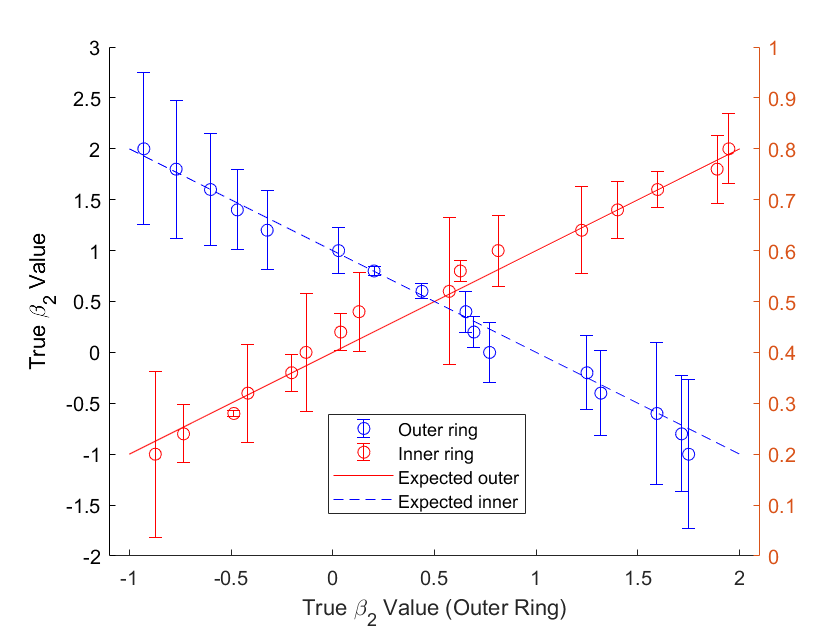

% plot(-1:0.2:2, -1:0.2:2)

figure()
hold on
errorbar(nonzeros(output_ring1_beta2)', -1:0.2:2, nonzeros(output_ring1_error)', nonzeros(output_ring1_error)', 'o', 'Color', 'blue')
yyaxis("left")
errorbar(nonzeros(output_ring2_beta2)', -1:0.2:2, nonzeros(output_ring2_error)', nonzeros(output_ring2_error)', 'o', 'Color', 'red')
plot(-1:0.2:2, -1:0.2:2, 'Color', 'red')
plot(-1:0.2:2, 2:-0.2:-1, 'Color', 'blue')
xlabel("True \beta_2 Value (Outer Ring)")
ylabel("True \beta_2 Value")
legend("Outer ring", "Inner ring", "Expected outer", "Expected inner", 'Position',[0.389880952380954 0.183730158730162 0.236309523809524 0.159126984126984]);
xlim([-1.1, 2.1])
ylim([-2, 3])

% plot(-1:0.2:2, -1:0.2:2)

% errors shown are the standard deviation of beta2 around both adjacent
% pixels of the peak

% errors would be reduced on higher image sizes as rings would be situated
% in more pixels